# 64 QAM modulation 

Set the simulation parameters.

clc % clears the screen
clear all % clears all variables
rng default
M = 64;                % Modulation order
k = log2(M);           % Bits per symbol
EbNoVec = (4:18)';     % Eb/No values (dB)
numSymbols = 600;     % Number of symbols to modulate

QAM model 

% Generate random binary data
dataBits = randi([0 1], numSymbols * k, 1);

c = zeros(M, 1);  % Pre-allocate the complex constellation array

for i = 0:(M-1)
    


RAPP Parameters 

% Define RAPP PA model parameters
A0 = 1.5;     % Limiting output amplitude
v = 1;      % Small signal gain
p = 3;      % Smoothness parameter


Initialize the BER and BLER results vectors.

berEstSoft = zeros(size(EbNoVec)); 
berEstHard = zeros(size(EbNoVec));
blerEstSoft = zeros(size(EbNoVec)); 
blerEstHard = zeros(size(EbNoVec));

Set the trellis structure and traceback depth for a rate 1/2, constraint length 7, convolutional code.

[`trellis`](https://www.mathworks.com/help/comm/ref/poly2trellis.html#mw_454b01d4-4916-487a-8e43-bc5099d2df39) `= poly2trellis(`[`ConstraintLength`](https://www.mathworks.com/help/comm/ref/poly2trellis.html#mw_04cd2efd-80ce-49c7-85c9-e6849b54faff)`,`[`CodeGenerator`](https://www.mathworks.com/help/comm/ref/poly2trellis.html#mw_79872670-4649-486d-b939-575fd51fac4b)`,`[`FeedbackConnection`](https://www.mathworks.com/help/comm/ref/poly2trellis.html#mw_fd809744-4f71-487e-86be-b4be5cb16dda)`)`

for every input bit, two encoded bits are generated.

Forward error corretion (FEC) 

ntroduces redundancy in transmitted data to allow error correction at the receiver. Instead of encoding data in fixed-size blocks (like block codes), convolutional encoders **spread the information across multiple output bits using shift registers**

- **Constraint Length (7)**:This means that the encoder uses **7 past bits** to determine the output.

- **Generator Polynomials ([171 133] in octal)**:These define how the input bit and its past values are combined to form encoded output bits.

- `171` in octal = `1 1 1 1 0 0 1` in binary

- `133` in octal = `1 1 0 0 1 1 1` in binary

- Each bit is XOR-ed according to these polynomials to generate **two output bits** for every **one input bit**.

trellis = poly2trellis(7,[171 133]);
tbl = 32;
rate = 1/2;

The main processing loops perform these steps:

- Generate binary data

- Convolutionally encode the data

- Apply QAM modulation to the data symbols. Specify unit average power for the transmitted signal

- Pass the modulated signal through an AWGN channel

- Demodulate the received signal using hard decision and approximate LLR methods. Specify unit average power for the received signal

- Viterbi decode the signals using hard and unquantized methods

- Calculate the number of bit errors

The `while` loop continues to process data until either 100 errors are encountered or  bits are transmitted.

for n = 1:length(EbNoVec)
    % Convert Eb/No to SNR
    snrdB = EbNoVec(n) + 10*log10(k*rate);
    % Noise variance calculation for unity average signal power
    noiseVar = 10.^(-snrdB/10);
     % Reset the error, bit, and block counters
    [numErrsSoft, numErrsHard, numBits] = deal(0);
    [numBlockErrsSoft, numBlockErrsHard, numBlocks] = deal(0);

    while numErrsSoft < 100 && numBits < 1e7
        % Generate binary data and convert to symbols
        dataIn = randi([0 1],numSymPerFrame*k,1);
        
        % Convolutionally encode the data
        dataEnc = convenc(dataIn,trellis);
        
        % QAM modulate
        txSig = qammod(dataEnc,M, ...
            InputType='bit', ...
            UnitAveragePower=true);
        
        % RAPP PA goes here 
        txSig_amp = abs(txSig);   % Get amplitudes
        txSig_phase = angle(txSig); % Get phases
        txSigAmpRAPP = RAPP_PA(txSig_amp, A0, v, p); % Apply RAPP
        %Signal coming out of RAPP - multiply by the exponential form
        txSigRAPP = txSigAmpRAPP .* exp(1j * txSig_phase); % Recombine
        energy= mean(abs(txSigRAPP).^2);
        % Pass through AWGN channel
        rxSig = awgn(txSigRAPP,snrdB,'measured');
        
        % Demodulate the noisy signal using hard decision (bit) and
        % soft decision (approximate LLR) approaches.
        rxDataHard = qamdemod(rxSig,M, ...
            OutputType='bit', ...
            UnitAveragePower=true);
        rxDataSoft = qamdemod(rxSig,M, ...
            OutputType='approxllr', ...
            UnitAveragePower=true, ...
            NoiseVariance=noiseVar);
        
        % Viterbi decode the demodulated data
        dataHard = vitdec(rxDataHard,trellis,tbl,'cont','hard');
        dataSoft = vitdec(rxDataSoft,trellis,tbl,'cont','unquant');
        
        % Calculate the number of bit errors in the frame. 
        % Adjust for the decoding delay, which is equal to 
        % the traceback depth.
        numErrsInFrameHard = ...
            biterr(dataIn(1:end-tbl),dataHard(tbl+1:end));
        numErrsInFrameSoft = ...
            biterr(dataIn(1:end-tbl),dataSoft(tbl+1:end));
        
        % Calculate block errors
        blockErrorHard = numErrsInFrameHard > 0; % Block error if any bit error occurs
        blockErrorSoft = numErrsInFrameSoft > 0;

        % Increment the error and bit counters
        numErrsHard = numErrsHard + numErrsInFrameHard;
        numErrsSoft = numErrsSoft + numErrsInFrameSoft;
        numBits = numBits + numSymPerFrame*k;

        numBlockErrsHard = numBlockErrsHard + blockErrorHard;
        numBlockErrsSoft = numBlockErrsSoft + blockErrorSoft;
        numBlocks = numBlocks + 1;

    end
    
    % Estimate the BER for both methods
    berEstSoft(n) = numErrsSoft/numBits;
    berEstHard(n) = numErrsHard/numBits;
    blerEstSoft(n) = numBlockErrsSoft / numBlocks;
    blerEstHard(n) = numBlockErrsHard / numBlocks;
end

Plot the estimated hard and soft BER data. Plot the theoretical performance for an uncoded 64-QAM channel.

Ber Resul;ts 

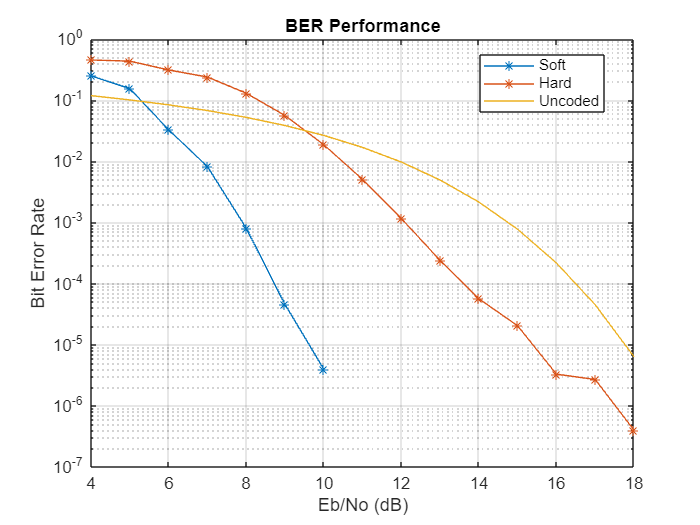

semilogy(EbNoVec,[berEstSoft berEstHard],'-*')
hold on
semilogy(EbNoVec,berawgn(EbNoVec,'qam',M))
legend('Soft','Hard','Uncoded','location','best')
grid on;
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
title('BER Performance');

BER results 

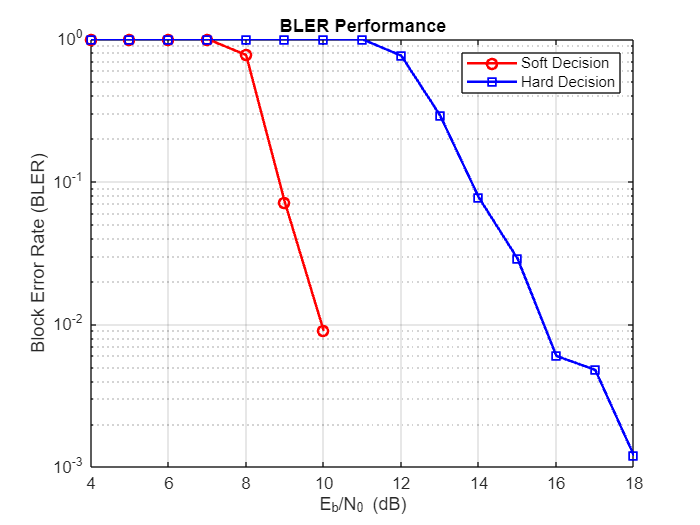

figure;
semilogy(EbNoVec, blerEstSoft, 'r-o', 'LineWidth', 1.5); hold on;
semilogy(EbNoVec, blerEstHard, 'b-s', 'LineWidth', 1.5);
xlabel('E_b/N_0 (dB)');
ylabel('Block Error Rate (BLER)');
title('BLER Performance');
legend('Soft Decision', 'Hard Decision');
grid on;

As expected, the soft decision decoding produces the best results. 